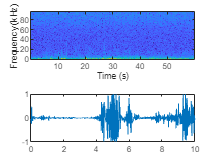

 % Load in audio and separate into different channels. The left channel
    % is always used in case the audio is mono or stereo.
    [audio,FS] = audioread("Leafyspurge/200805_002.WAV");
    audioL = audio(:,1);

    % Determine the number of 5 second segments that the audio can be
    % split into, rounded up, and pads the audio to an even length.
    numSegments = ceil(length(audioL)/(.25*FS));
    audioLabels = zeros(length(audioL),1);
    popCount = 0;

    t = 0:1/FS:(length(audioL((3*60+45)*FS:(3*60+55)*FS))-1)/FS;
    plot(t,audioL((3*60+45)*FS:(3*60+55)*FS));

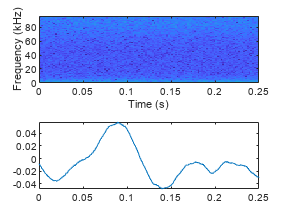


    figure(1); clf;
    tiledlayout(2,1);
    p1 = nexttile;
    spectrogram(audioL((3*60)*FS:(4*60)*FS),hann(512),128,512,FS,'yaxis'); colorbar off; hold on;
    p2 = nexttile;
    t = 0:1/FS:(length(audioL((3*60)*FS:(4*60)*FS))-1)/FS;
    plot(t,audioL((3*60)*FS:(4*60)*FS));

    p1.XLim = [0 .25];
    p2.XLim = [0 .25];